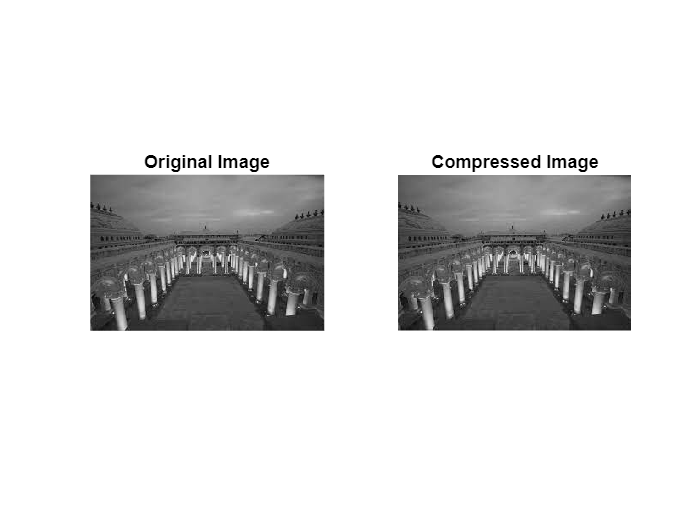

% Load the image
img = imread('mahal.jpg');

% Convert the image to grayscale
img_gray = rgb2gray(img);

% Perform DWT on the image
[cA, cH, cV, cD] = dwt2(img_gray, 'haar');

% Set a threshold value for compression
threshold = 0.1;

% Apply soft thresholding to the coefficients
cA = wthresh(cA, 's', threshold);
cH = wthresh(cH, 's', threshold);
cV = wthresh(cV, 's', threshold);
cD = wthresh(cD, 's', threshold);

% Reconstruct the compressed image
img_comp = idwt2(cA, cH, cV, cD, 'haar');

% Display the original and compressed images
subplot(1,2,1), imshow(img_gray), title('Original Image');
subplot(1,2,2), imshow(uint8(img_comp)), title('Compressed Image');

whos img_comp

  Name            Size              Bytes  Class     Attributes

  img_comp      184x276            406272  double              



whos img_gray

  Name            Size             Bytes  Class    Attributes

  img_gray      183x275            50325  uint8              

